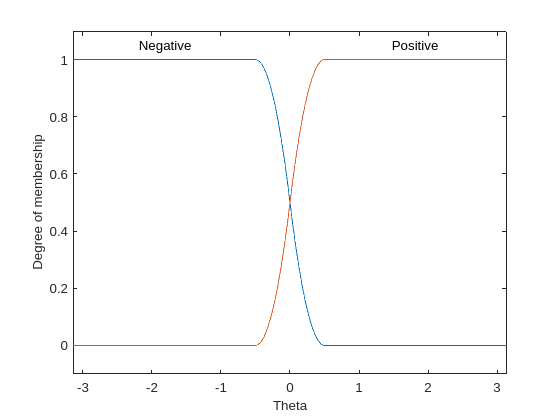

% Cart/Pole Fuzzy Inference System

cartpole1FIS = mamfis(...
    'NumInputs',1,'NumInputMFs',2,...
    'NumOutputs',1,'NumOutputMFs',2,...
    'AddRule','none');

%Inputs
cartpole1FIS.Inputs(1).Name = 'Theta';
cartpole1FIS.Inputs(1).Range = [-pi pi];
cartpole1FIS.Inputs(1).MembershipFunctions(1).Name = 'Negative';
cartpole1FIS.Inputs(1).MembershipFunctions(1).Type = 'zmf';
cartpole1FIS.Inputs(1).MembershipFunctions(1).Parameters = [-0.5 0.5];
cartpole1FIS.Inputs(1).MembershipFunctions(2).Name = 'Positive';
cartpole1FIS.Inputs(1).MembershipFunctions(2).Type = 'smf';
cartpole1FIS.Inputs(1).MembershipFunctions(2).Parameters = [-0.5 0.5];

plotmf(cartpole1FIS,'input',1,1000);

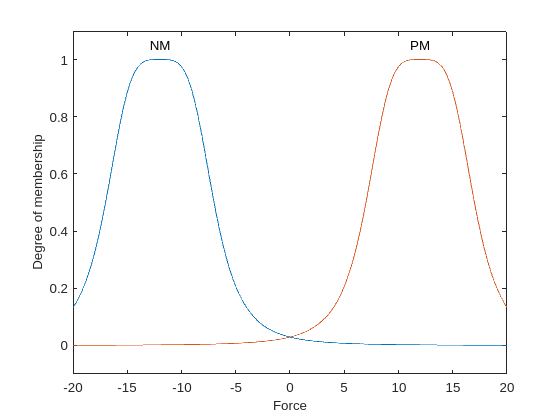

%Outputs
cartpole1FIS.Outputs(1).Name = 'Force';
cartpole1FIS.Outputs(1).Range = [-20 20];
cartpole1FIS.Outputs(1).MembershipFunctions(1).Name = 'NM';%Negative Medium
cartpole1FIS.Outputs(1).MembershipFunctions(1).Type = 'gbellmf';
cartpole1FIS.Outputs(1).MembershipFunctions(1).Parameters = [5 2 -12];
cartpole1FIS.Outputs(1).MembershipFunctions(2).Name = 'PM';%Positive Medium
cartpole1FIS.Outputs(1).MembershipFunctions(2).Type = 'gbellmf';
cartpole1FIS.Outputs(1).MembershipFunctions(2).Parameters = [5 2 12];

plotmf(cartpole1FIS,'output',1,1000);

%Specify Rules
rules = [...
    "If Theta is Negative then Force is NM";...
    "If Theta is Positive then Force is PM"];

cartpole1FIS = addRule(cartpole1FIS,rules);